# **Sequence Alignment Assignment: **

**Bianca Caissotti di Chiusano (i6245461)**

Another friend of Peter’s studies unicellular microalgae (symbiodinium necroappetens) which also have a RING1 protein, but it is much longer than the human version.  The accession number of this protein is CAE7901930. How close is the algae version to the human protein?  Explain your results.

The sequence alignment problem is used to understand how closely two sequence are related to each other. The first step is to extract the Algae and Human RING1 protein with the command **getgenpept.**

Algae_RING1 = getgenpept('CAE7901930', "SequenceOnly",true)

Algae_RING1 = 'MASFAPLRRSRGLALLVLSLPLCCFVSAWGTARGRRVEYQARHAAPEPAEPELASPAWEESAQVVLEIVEDSTKEDALDWLQAGYAWTAKSRRFWRKLRSPMPPEPEAVRRTARWLQDKGLAQKAWVRRFPEVLGLSVEDLEEGRSTAPSYLKSEDTYNKAIKSNPTLLGKNYDCLQEHESCQGRCSRCWNTTDAEQSEQYTLCGCLGFLGGLSILENIGPLKLRAGSSSGTVSGLSSISGSSYQAAMKHALLLLALPAHATQISTEDPALLSDEQASLREEDEWRPSAQATFPRPSYGNGWSPWSGNPGSLPGGPAAHLPYQAVPRVPAPPPAGTFPKVAVSSAASGAGPNNLKEAEAETKKFFEIEEMVAKETGLPLNSSEAAQKEEEEKAEAKEVEEEEEEERFDALYAGIALVILLAAGGTFYFHRWSQDKPKPGEALGAAAPSSPEADPKAPGPAEAEAKAATGRMKRKLLQLQVLILLSPLSEGPLSCQWGERWPLPDPSPSEGAMGKKRKAEFEPPPVNLDALPPLEEGILRFEFTLEEKGALGVRFSGGSPPMILSVAPDSFASKKGIPVNYEVHAINGLALVQQNQQRVMHFLKSRPVVLDVRPLGWKPPEKMKELKRRQQQEEAEQKAKMAVEKKRREQDGWKVEMHSEEIQQFNADVRQVFSSVFSACTWLSKPNERSPQLVPQKPLPLGQNQLRVCEELERLGLLKASPLPSPFVVAFHELLSSPVGGECSCGAMGDLPFSLAALLNSGAGALGPAREGGTITLLTLPGRGLVGAAITPSGSEPGFPLPLGLLQSLGGQVSRVPVAAEEDAADALGGIMRMMMEQMAQIAMQRSMEESGPKVPPASERVRDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANTCPVCRYELATDCEDFESGRRTRMSGRIVRLRAAELRMLRISELRRLMDALGVSGEGCLERADLVRH

Human_RING1 = getgenpept('CAA78389', "SequenceOnly",true)

Human_RING1 = 'MDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGCGGEGGGAGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'

With the command seqdotplot we can generate a dot plot used to visualise the matches between the two sequences. Every dot, signifies a match. 

We can make some observations, such as that the Algae sequence (Sequence 1) is much longer than the Human sequence (Sequence 2). The latter may also imply that executing a local alignment would be better than a global alignment, because of the amount of gaps that would be required to perform a global alignment, and its impact on the alignment score.

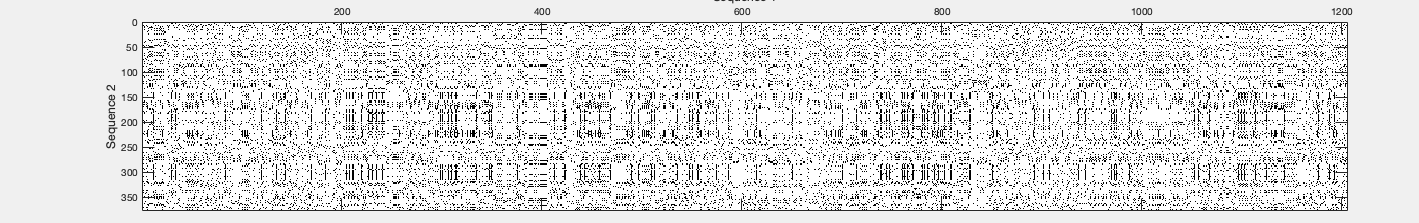

Matches = seqdotplot(Algae_RING1, Human_RING1);

## Global Alignment with BLOSUM50

We now use the command nwalign(Seq1,Seq2) to find the optimal global alignment of the two sequences. By default MatLab uses BLOSUM50 as a substitution matrix used to calculate both local and global alignments and their alignment scores of proteins. 

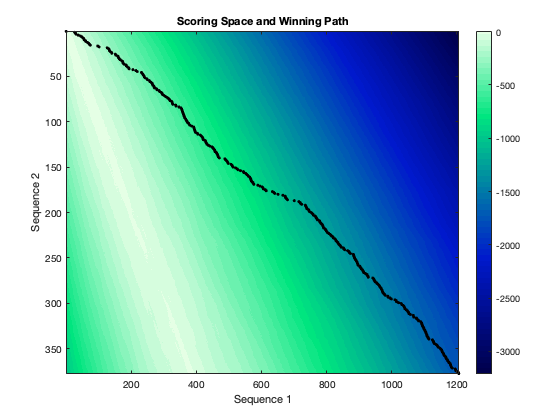

global_align_score = -1738

global_alignment = 3×1206 char array
    'MASFAPLRRSRGLALLVLSLPLCCFVSAWGTARGRRVEYQARHAAPEPAEPELASPAWEESAQVVLEIVEDSTKEDALDWLQAGYAWTAKSRRFWRKLRSPMPPEPEAVRRTARWLQDKGLAQKAWVRRFPEVLGLSVEDLEEGRSTAPSYLKSEDTYNKAIKSNPTLLGKNYDCLQEHESCQGRCSRCWNTTDAEQSEQYTLCGCLGFLGGLSILENIGPLKLRAGSSSGTVSGLSSISGSSYQAAMKHALLLLALPAHATQISTEDPALLSDEQASLREEDEWRPSAQATFPRPSYGNGWSPWSGNPGSLPGGPAAHLPYQAVPRVPAPPPAGTFPKVAVSSAASGAGPNNLKEAEAETKKFFEIEEMVAKETGLPLNSSEAAQKEEEEKAEAKEVEEEEEEERFDALYAGIALVILLAAGGTFYFHRWSQDKPKPGEALGAAAPSSPEADPKAPGPAEAEAKAATGRMKRKLLQLQVLILLSPLSEGPLSCQWGERWPLPDPSPSEGAMGKKRKAEFEPPPVNLDALPPLEEGILRFEFTLEEKGALGVRFSGGSPPMILSVAPDSFASKKGIPVNYEVHAINGLALVQQNQQRVMHFLKSRPVVLDVRPLGWKPPEKMKELKRRQQQEEAEQKAKMAVEKKRREQDGWKVEMHSEEIQQFNADVRQVFSSVFSACTWLSKPNERSPQLVPQKPLPLGQNQLRVCEELERLGLLKASPLPSPFVVAFHELLSSPVGGECSCGAMGDLPFSLAALLNSGAGALGPAREGGTITLLTLPGRGLVGAAITPSGSEPGFPLPLGLLQSLGGQVSRVPVAAEEDAADALGGIMRMMMEQMAQIAMQRSMEESGPKVPPASERVRDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANTCPVCRYELATDCEDFESGRRTRMSGRIVRLRAAELRMLR

[global_align_score, global_alignment] = nwalign(Algae_RING1, Human_RING1, 'ShowScore', true)

We can observe that if we do a traceback of the "winning path" is almost always never diagonal. In fact, a diagonal step would simplify a match or mismatch. While it makes sense that we observe more vertical and horizonal steps that signify gap insertions, especially in the second sequence (Human RING1 protein), as it is much shorter than the first sequence.

The Optimal global alignmnet has a very low score. A low score signifies that the two sequences are not closely related, meaning that much time has passed since they shared a common ancestor. 

## Local Alignment with BLOSUM50

Performing the optimal Local alignment of the two sequences using the command **swalign**

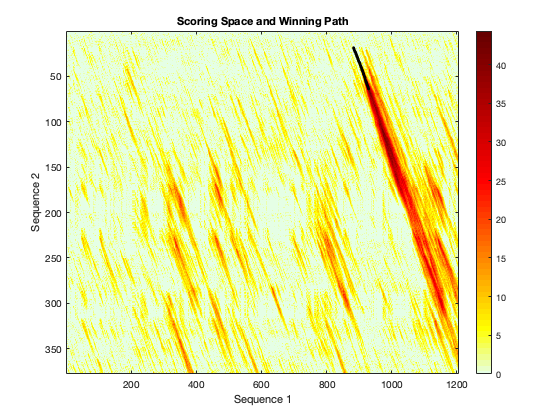

local_align_score = 44.3333

local_alignment = 3×48 char array
    'CSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREAN-TCPVCRYELAT'
    '| :|| |:  :: :|:  | | ||: ||   || :|  ||:|| :|::'
    'CPICL-DMLKNTMTTKE-CLHRFCSDCIVTALRSGNKECPTCRKKLVS'


[local_align_score, local_alignment] = swalign(Algae_RING1, Human_RING1, 'ShowScore', true)

With the local alignment we try to find the best global alignment over all the possible subsequences of the sequences. Here we see a less overwhelming alignment score, compared to the global alignment.

## Global Alignment with BLOSUM30 

Because Matlabs default substitution matrix is BLOSUM50, it was interesting to calculate again the global and local alignments of the sequences with a different substritution matrix. Blosum30 was chosen. 

From what I understood, BLOSUM30 is used for sequences that are not closely related, such as the ones we are dealing with, while BLOSUM50 and higher is for more closely related sequences. 

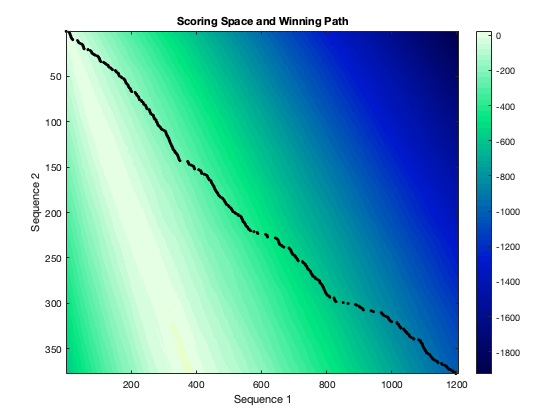

global_align_score_30 = -1.0216e+03

global_alignment_30 = 3×1206 char array
    'MASFAPLRRSRGLALLVLSLPLCCFVSAWGTARGRRVEYQARHAAPEPAEPELASPAWEESAQVVLEIVEDSTKEDALDWLQAGYAWTAKSRRFWRKLRSPMPPEPEAVRRTARWLQDKGLAQKAWVRRFPEVLGLSVEDLEEGRSTAPSYLKSEDTYNKAIKSNPTLLGKNYDCLQEHESCQGRCSRCWNTTDAEQSEQYTLCGCLGFLGGLSILENIGPLKLRAGSSSGTVSGLSSISGSSYQAAMKHALLLLALPAHATQISTEDPALLSDEQASLREEDEWRPSAQATFPRPSYGNGWSPWSGNPGSLPGGPAAHLPYQAVPRVPAPPPAGTFPKVAVSSAASGAGPNNLKEAEAETKKFFEIEEMVAKETGLPLNSSEAAQKEEEEKAEAKEVEEEEEEERFDALYAGIALVILLAAGGTFYFHRWSQDKPKPGEALGAAAPSSPEADPKAPGPAEAEAKAATGRMKRKLLQLQVLILLSPLSEGPLSCQWGERWPLPDPSPSEGAMGKKRKAEFEPPPVNLDALPPLEEGILRFEFTLEEKGALGVRFSGGSPPMILSVAPDSFASKKGIPVNYEVHAINGLALVQQNQQRVMHFLKSRPVVLDVRPLGWKPPEKMKELKRRQQQEEAEQKAKMAVEKKRREQDGWKVEMHSEEIQQFNADVRQVFSSVFSACTWLSKPNERSPQLVPQKPLPLGQNQLRVCEELERLGLLKASPLPSPFVVAFHELLSSPVGGECSCGAMGDLPFSLAALLNSGAGALGPAREGGTITLLTLPGRGLVGAAITPSGSEPGFPLPLGLLQSLGGQVSRVPVAAEEDAADALGGIMRMMMEQMAQIAMQRSMEESGPKVPPASERVRDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANTCPVCRYELATDCEDFESGRRTRMSGRIVRLRAAELR

[global_align_score_30, global_alignment_30] = nwalign(Algae_RING1, Human_RING1, 'ShowScore', true, ScoringMatrix="BLOSUM30")

## Local Alignment with BLOSUM30

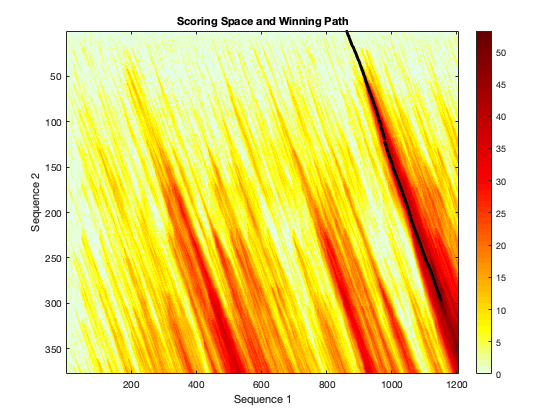

local_align_score_30 = 53.2000

local_alignment_30 = 3×306 char array
    'RDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANT-CPVCRYELATDCEDFESGRRTRMSGRIVRLRAA-ELRMLRI-SELRRLMD--ALGVSG-EGC-LE---RADLV-RHLEGAPDVEVAPELSAEK-KFRYDLQDLEQLDLPLLRNLMERHRVPFDLEEDLSEDDERRVALRSF-ADAG-WMRGA-SKTPPKPSEGAKQMPARPENTTEPAQTTTAAFVPSTDAGESGESGESEMRSETPSGESCEAKSRAAGKAARPA-EPPPARRRPRPGAKAEAKAD'
    ':|::: ::|:: :| :::  :| :|| |  :::::| : | | ||: ||   ||::|  ||:|| :|::: :  ::     : ::|:  |:: |    |:   | ||::  ||: |  ||: ::   ||  | |:::|:  : ::   ::|: :   | :|::  : |   :  : :: |    :  |:      :: :: : ||    |: : |    : | :  |: | :::||:  :  :| | :   |:||  :: :: :| :| :  ::  ::  | | | |  :::    ||::: :::|'
    'MDGTE-IAVSPRSLHSEL--MCPICL-DMLKNTMTT-KECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAP-DSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAP-SPPEPGGEIELVFRPHPLLVEKGEYCQT-RYVKT-TGNA-TVDHLSKYLALRIALERRQQQEAGEPGGPGGGASD'


[local_align_score_30, local_alignment_30] = swalign(Algae_RING1, Human_RING1, 'ShowScore', true, ScoringMatrix="BLOSUM30")

With BLOSUM30, both the global and local alignments have a higher alignment score compared to when calculated with BLOSUM50. Thus BLOSUM30 will be used for the rest of the experiments.

## More experiments Local Alignment with BLOSUM62 and PAM250

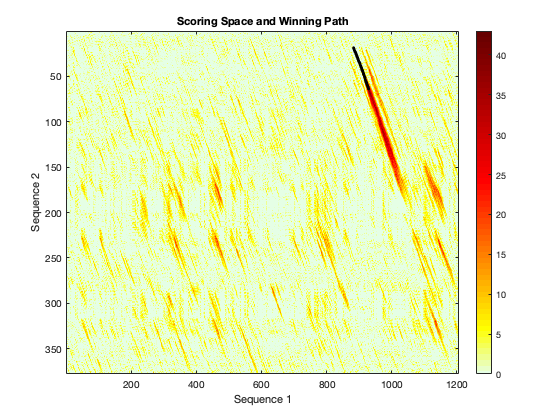

local_align_score_62 = 43

local_alignment_62 = 3×48 char array
    'CSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREAN-TCPVCRYELAT'
    '| :|| |   :: :|:  | | ||: ||   ||::|  ||:|| :|::'
    'CPICL-DMLKNTMTTKE-CLHRFCSDCIVTALRSGNKECPTCRKKLVS'


[local_align_score_62, local_alignment_62] = swalign(Algae_RING1, Human_RING1, 'ShowScore', true, ScoringMatrix="BLOSUM62")

Through the years, BLOSUM62 was found to be not very accurate. We are clustering at a 62% level. No change is observed however.

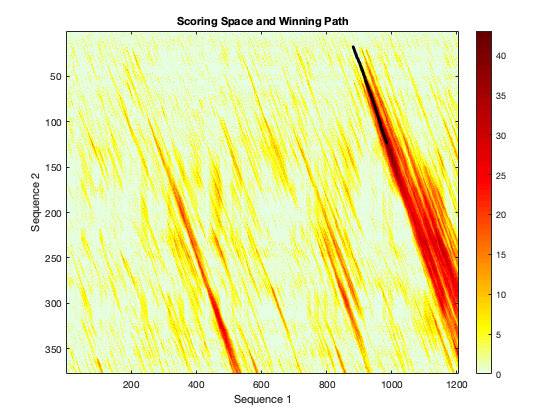

local_align_score_pam = 43

local_alignment_pam = 3×109 char array
    'KCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREAN-TCPVCRYELATDCEDFESGRR-TRMSGRIVRLRAA-ELRMLRI-SELRRL--MDALGVSGEGCLERADLVR'
    ':|::||:  :::: :|:  | | ||::|| : ||::| :||:|| :|:::  :: :::: : : ::| : |:: | :  |:   |:||   :||: | |: | :::: |'
    'MCPICLDMLKNTM-TTKE-CLHRFCSDCIVTALRSGNKECPTCRKKLVSK-RSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHR'


[local_align_score_pam, local_alignment_pam] = swalign(Algae_RING1, Human_RING1, 'ShowScore', true, ScoringMatrix="PAM250")

Based on Research, PAM250 is more forgiving of mismatches. We can see that the best local alignment found is much larger in length of the subsequence, compared to when using BLOSUM. Nevertheless, the score remains the same.

## Significance of the scores with randperm

Now that we have determined the alignment scores we need to asses their significance to determine whether these scores are due to chance or biology.

We do this by generating random protein sequences of that have the same properties of the Human RING1 protein, and finding the optimal global and local alignments with the Algae RING1 protein.

We first use the command **randperm** to permute the data of the Human protein and generate 1000 different sequences to align with the Algae protein.

score_global_array = zeros();
score_local_array = zeros();
score_global_array(1) = global_align_score_30

score_global_array = -1.0216e+03

score_local_array(1) = local_align_score_30

score_local_array = 53.2000

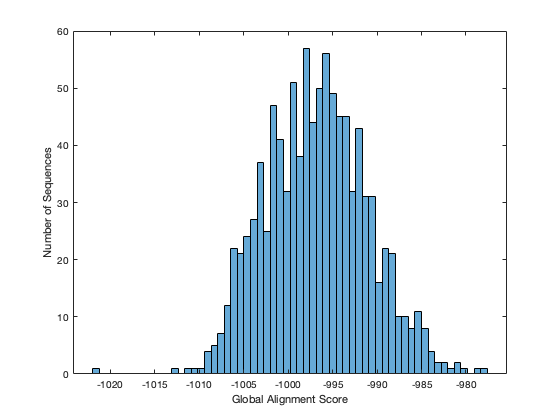

count_LScore = 0;
% Generate multiple random sequences
for i = 2 : 1001
    permuted_order = randperm(length(Human_RING1), length(Human_RING1));
    permuted_human = Human_RING1(permuted_order);
    gPerm_score = nwalign(Algae_RING1, permuted_human, ScoringMatrix="BLOSUM30");
    lPerm_score = swalign(Algae_RING1, permuted_human, ScoringMatrix="BLOSUM30");
    if lPerm_score >= local_align_score_30
        count_LScore = count_LScore + 1;
    end
    score_global_array(i) = gPerm_score;
    score_local_array(i) = lPerm_score;
end

figure;
histogram(score_global_array, 60);
ylabel("Number of Sequences")
xlabel("Global Alignment Score")

The bin at the global alignment score lower than -1020 is the original optimal global alignment between the original Human protein and the Algae protein. From the histogram we can observe that the alignment scores when aligning the permuted sequences with the Algae sequence are still quite low, most likely because of the big difference in length. However all scores are higher than the original score. Thus we can conclude that the global alignment score is significant.

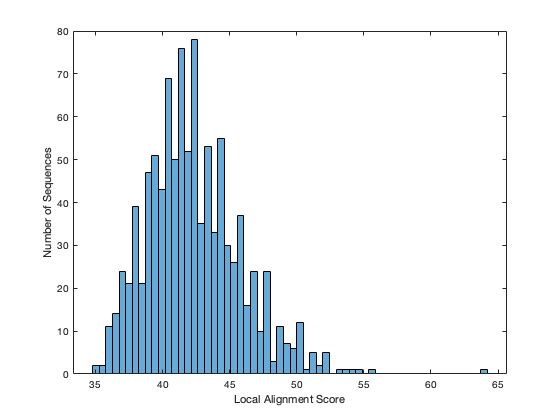

figure;
histogram(score_local_array, 60);
ylabel("Number of Sequences")
xlabel("Local Alignment Score")

count_LScore

count_LScore = 5

Unlike, with the global alignment, when assessing the significance of the local alignment it was found that there were 5 cases in which the local alignment score was equal or greater than the original score.

Thus, if 5 times out of 1000 permutations the alignment score was equal or greater than the observed score, the P-value is 0.005, making the original local alignment also significant, as such a score would be given by change less the 1% of the time.

## Significance with aacount

Another way to generate random sequences instead of permuting the original sequence, is to generate a new sequence with the same amino acid distribution as the original shorter sequence, thus the Human RING1 protein.

We use the **aacount** command.

count_aminoAcid = aacount(Human_RING1)

count_aminoAcid = struct with fields:
    A: 23
    R: 24
    N: 7
    D: 18
    C: 10
    Q: 11
    E: 31
    G: 63
    H: 7
    I: 12
    L: 31
    K: 16
    M: 7
    F: 5
    P: 34
    S: 31
    T: 23
    W: 1
    Y: 8
    V: 15


random_sequence = randseq(length(Human_RING1),'FromStructure',count_aminoAcid)

random_sequence = 'QGDSSGGRHVSTQVSDDSLTERTEQRGMGCGQEGPGGRETRLKGDYQKLGIPVPIILEPGNPGAPQGGMGIGYVELGLTGRTPTGMGKGEPKVKGFVKKHGSVSRSVGSKTNHSAGDEVGGGRLSCVVNEGCPQEKVNKCGVVSRISAGSDAERHMKPGRAASGIMVNAILPYLPSGGALSQNNPGKIRRGGPHPGARLSADNELDPPRGQLMNPHAPVTEVMPGQGKPGVGYGRILDPPLAKEKGVMGPSTDSGSIFTVTTEASDGVKQAGSSKPVNRGVHDESREVGYPDEPSGGADRELKFGVGPPLEDEDSEDGLQAKDGESPKSGTLPGTLKIEGICHTKTGRMEGVIILTLTNPRSSVCCSGITPPRSRER'

score_global_array_2 = zeros();
score_local_array_2 = zeros();

score_global_array_2(1) = global_align_score_30

score_global_array_2 = -1.0216e+03

score_local_array_2(1) = local_align_score_30

score_local_array_2 = 53.2000

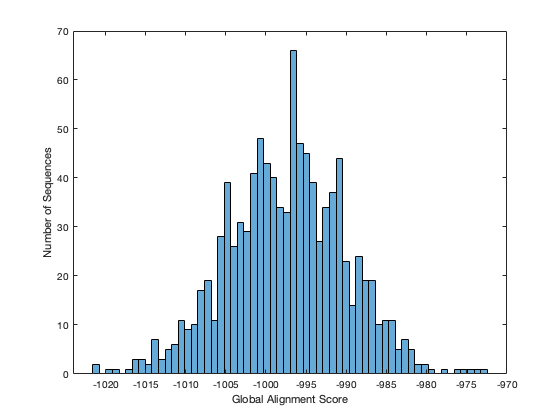

% Generate multiple random sequences
count_G = 0;
count_L = 0;
for i = 2 : 1001
    random_sequence = randseq(length(Human_RING1),'FromStructure',count_aminoAcid);
    gPerm_score_2 = nwalign(Algae_RING1, random_sequence, ScoringMatrix="BLOSUM30");
    if gPerm_score_2 <= global_align_score_30
        count_G = count_G + 1;
    end
    lPerm_score_2 = swalign(Algae_RING1, random_sequence, ScoringMatrix="BLOSUM30");
    if lPerm_score_2 >= local_align_score_30
        count_L = count_L +1 ;
    end
    score_global_array_2(i) = gPerm_score_2;
    
    score_local_array_2(i) = lPerm_score_2;
end

figure;
histogram(score_global_array_2, 60);
ylabel("Number of Sequences")
xlabel("Global Alignment Score")

count_G

count_G = 0

Also in this case we can see that the results remain significant. 

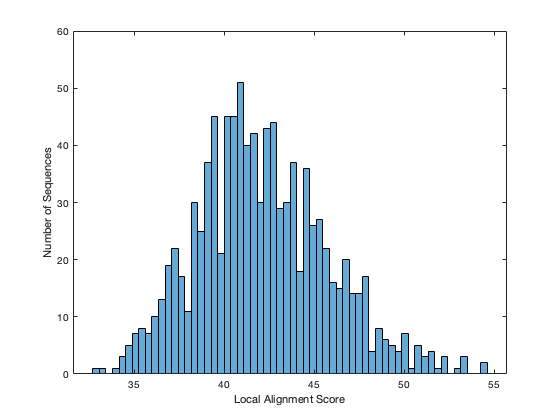

figure;
histogram(score_local_array_2, 60);
ylabel("Number of Sequences")
xlabel("Local Alignment Score")

count_L

count_L = 4

Same can be said of the local alignment scores. 4 out of 1000 randomly generated sequences have an equal or greater alignmnet score. Thus, the P-value is 0.004, so the original alignment remains significant.

Overall, however, I would conclude that for such different protein sequence lengths, a local alignment is more suitable to explore the relationship of the sequences. 

Especially when plotting the histograms to assess the significance of the alignment scores, the original global alignment score was almost always the lowest, while it was more intuitive to observe the signifiance of the local alignment scores. 

Nevertheless, to conclude, both original alignment scores were significant.